close all;
clear variables;


## Калибровка

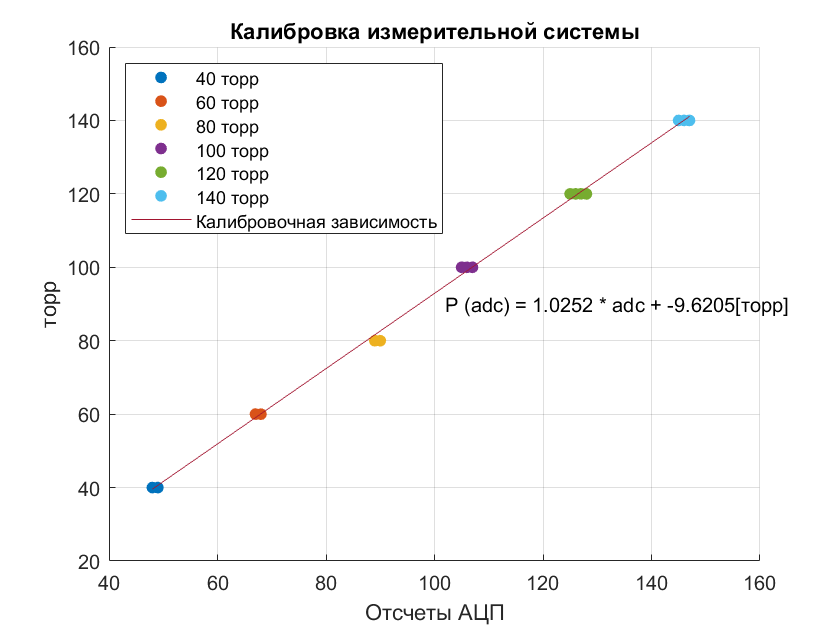

adc40 = fscanf(fopen('data/calibration_1.txt'), '%d');
adc60 = fscanf(fopen('data/calibration_2.txt'), '%d');
adc80 = fscanf(fopen('data/calibration_3.txt'), '%d');
adc100 = fscanf(fopen('data/calibration_4.txt'), '%d');
adc120 = fscanf(fopen('data/calibration_5.txt'), '%d');
adc140 = fscanf(fopen('data/calibration_6.txt'), '%d');

fclose('all');

torr40 = ones(length(adc40), 1) * 40;
torr60 = ones(length(adc60), 1) * 60;
torr80 = ones(length(adc80), 1) * 80;
torr100 = ones(length(adc100), 1) * 100;
torr120 = ones(length(adc120), 1) * 120;
torr140 = ones(length(adc140), 1) * 140;

cAdc = [adc40; adc60; adc80; adc100; adc120; adc140];
cTorr = [torr40; torr60; torr80; torr100; torr120; torr140];

c = polyfit(cAdc, cTorr, 1);

cFigure = figure('Name', 'Калибровка', 'NumberTitle', 'off');
hold all;

plot(adc40, torr40, '.', 'MarkerSize', 20);
plot(adc60, torr60, '.', 'MarkerSize', 20);
plot(adc80, torr80, '.', 'MarkerSize', 20);
plot(adc100, torr100, '.', 'MarkerSize', 20);
plot(adc120, torr120, '.', 'MarkerSize', 20);
plot(adc140, torr140, '.', 'MarkerSize', 20);

plot(cAdc, polyval(c, cAdc));

legend('40 торр', '60 торр', '80 торр', '100 торр', '120 торр', '140 торр', 'Калибровочная зависимость', 'Location', 'NorthWest');
grid on;
xlabel('Отсчеты АЦП');
ylabel('торр');
title('Калибровка измерительной системы');
text(mean(cAdc) * 1.05, mean(cTorr), ['P (adc) = ', num2str(c(1)),' * adc + ', num2str(c(2)), '[торр]']);
saveas(cFigure, 'Калибровка.png');

## Визуализация измерений

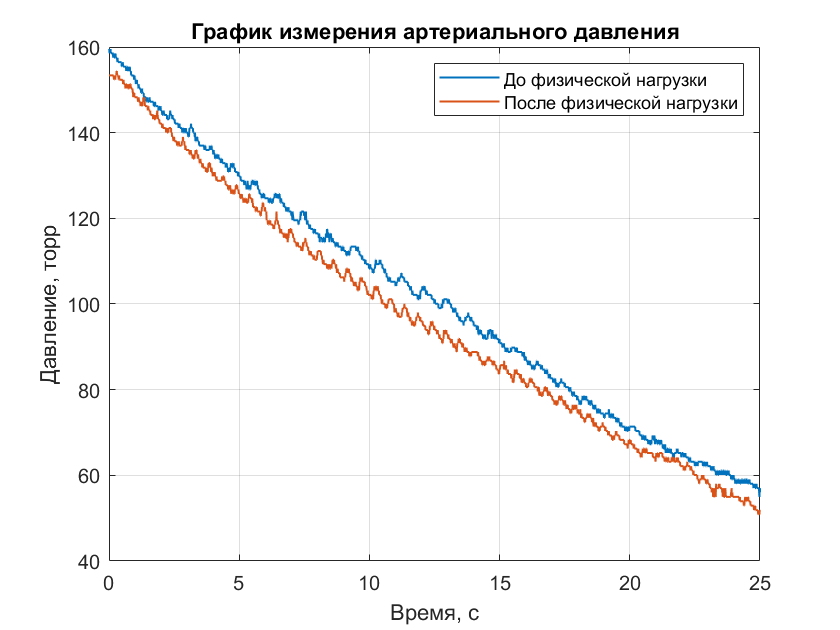

dt = 0.01; % секунды
adcBefore = fscanf(fopen('data/data_before.txt'), '%d');
tBefore = linspace(0, length(adcBefore) * dt, length(adcBefore));
pBefore = polyval(c, adcBefore);

adcAfter = fscanf(fopen('data/data_after.txt'), '%d');
tAfter = linspace(0, length(adcAfter) * dt, length(adcAfter));
pAfter = polyval(c, adcAfter);

pFigure = figure('Name', 'Графики давления', 'NumberTitle', 'off');

plot(tBefore, pBefore, tAfter, pAfter, 'LineWidth', 1);
legend('До физической нагрузки', 'После физической нагрузки');

grid on;
xlim([0, 25]);

xlabel('Время, с');
ylabel('Давление, торр');
title('График измерения артериального давления');

saveas(pFigure, 'Давление.png');

## Обработка

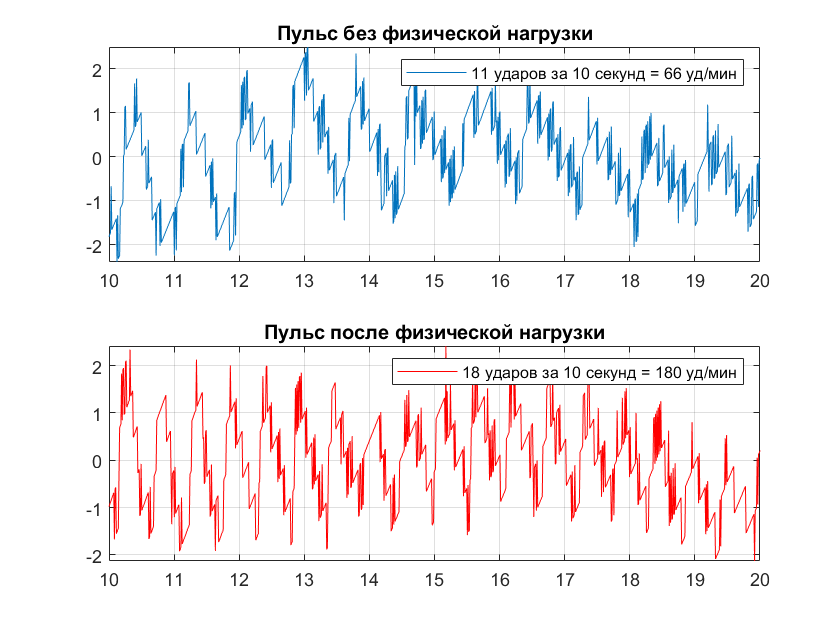

cBefore = polyfit(tBefore, pBefore, 7);
cAfter = polyfit(tAfter, pAfter, 5);

pulseBefore = pBefore - polyval(cBefore, tBefore)';
pulseAfter = pAfter - polyval(cAfter, tAfter)';

pulseFigure = figure('Name', 'Графики пульса', 'NumberTitle', 'off');

subplot(2, 1, 1);
plot(tBefore, pulseBefore);
legend('11 ударов за 10 секунд = 66 уд/мин');
grid on;
xlim([10, 20]);
title('Пульс без физической нагрузки');

subplot(2, 1, 2);
plot(tAfter, pulseAfter, 'r');
legend('18 ударов за 10 секунд = 180 уд/мин');
title('Пульс после физической нагрузки');
grid on;
xlim([10, 20]);

saveas(pulseFigure, 'Пульс.png');